# Partial Pivoting

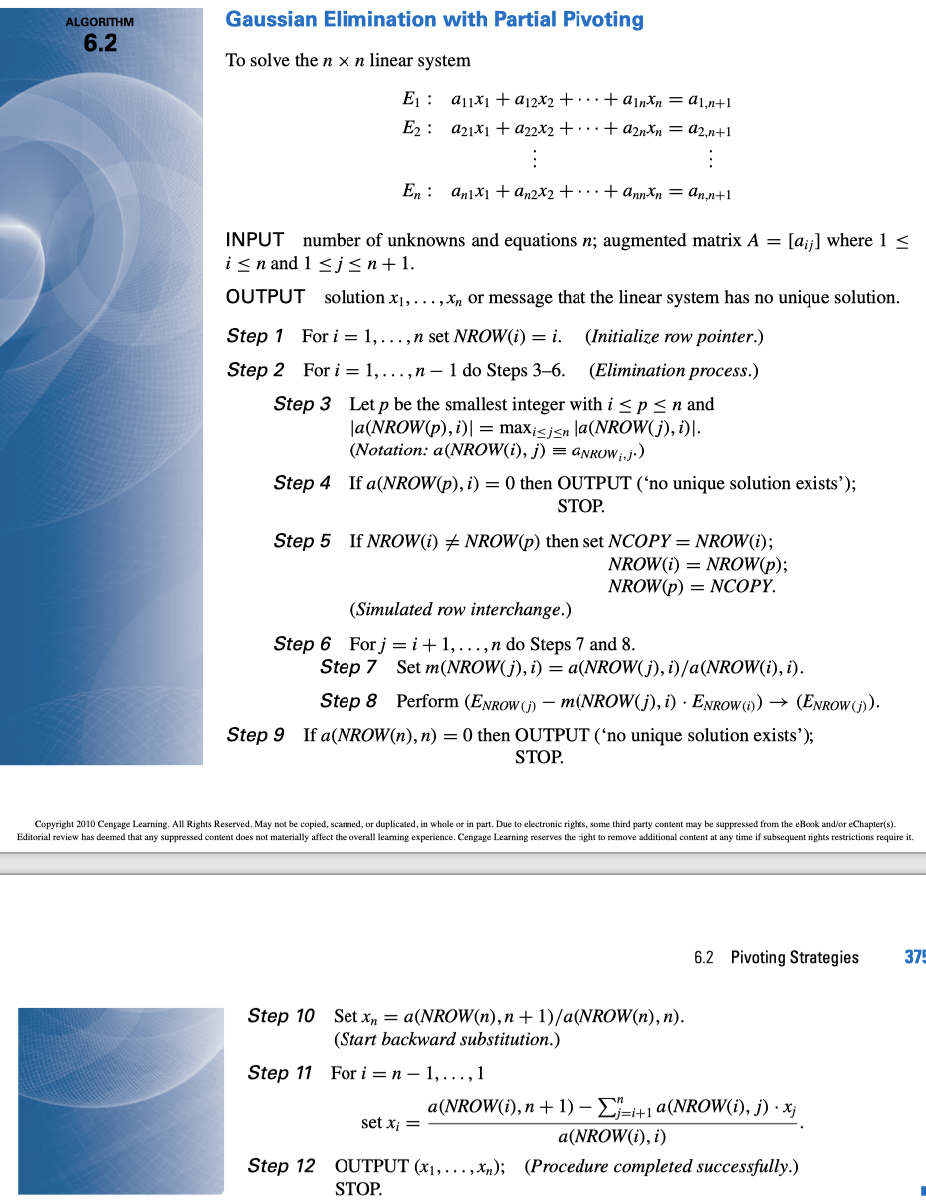

clc;clear;close all;

A=[0.003,59.14;
   5.291,-6.130];
B=[59.17;46.78];

Ag={};                                                  %Create a cell array to store each matrix
Aau=[A,B];                                              %Generate the augmented matrix
Ag{1}=Aau;                                              %Store the first initial matrix
[n,b]=size(A);
m=[];
NROW=[];
for i= 1:n                                              %Initialize row pointer
    NROW(i)=i;
end





for i=1:n-1
    %Check and switch to check pivot to be not 0
    p=i;
    %compare and find the max in column i between i and n row
    for j=i:n
        if abs(Aau(NROW(p),i))<abs(Aau(NROW(j),i))
            p=j;
        end
    end

    %Check not to be 0 with nonuniqueness solution
    if abs(Aau(NROW(p),i))==0
        disp("No unique Solution exist");
        break
    end
    %Change the row i and row p
    if NROW(i) ~= NROW(p)
        NCOPY=NROW(i);
        NROW(i)=NROW(p);
        NROW(p)=NCOPY;
    end

    for j=i+1:n
        m(NROW(j),i)=Aau(NROW(j),i)/Aau(NROW(i),i);
        Aau(NROW(j),:)=Aau(NROW(j),:)-m(NROW(j),i).*Aau(NROW(i),:);
    end

    Aaucopy=[];

    for k=1:n
        Aaucopy=[Aaucopy;Aau(NROW(k),:)];
    end
    Ag{i +1}=Aaucopy;

 
end


if Aau(NROW(n),n)== 0
    disp("No unique Solution Exist");
else
    % Start the backward substituition
    x=[];
    x(n)=Aau(NROW(n),n+1)/Aau(NROW(n),n);
        
    for i=n-1:-1:1
        sum=0;
        for j=i+1:n
            sum=sum+Aau(NROW(i),j)*x(j);
        end
        x(i)=(Aau(NROW(i),n+1)-sum)/Aau(NROW(i),i);
    end
    disp(x);
end

    10     1

